# The Hodgkin–Huxley model

If $I$ is the total membrane current, and $V_m$ is the potential difference across the neuron's membrane memberane, then these two quantities are related by


$$I=C_{m\;} \frac{{\textrm{dV}}_m \;}{\textrm{dt}}+g_K \left(V_m -V_k \right)+g_{\textrm{Na}} \left(V_m -V_{\textrm{Na}} \right)+g_l \left(V_m -V_l \right)$$


where $g_k$ and $g_{\textrm{Na}}$ are the potassium and sodium conductances per unit area, which is time-variant and dependent on $V_m$.

% I = Cm * Vmdot + gK * (Vm - Vk) + gNa * (Vm - VNa) + gL * (Vm - VL)

Noting that these conductance depend on the state of voltage-gated ion channels, so we model these conductance using the following equations:


$$\begin{array}{l}
g_K =\bar{\;g_K } n^{4\;} \\
g_{\textrm{Na}} =\bar{\;g_{\textrm{Na}} } m^3 h
\end{array}$$


% gK = gKmax * n^4
% gNa = gNamax * m^3 * h

where $n$, $m$ and $h$ are "are dimensionless probabilities between 0 and 1 that are associated with (or represent) potassium channel subunit activation, sodium channel subunit activation, and sodium channel subunit inactivation". (Adapted from Wikipedia)

We model these subunits' (in)activations by


$$\begin{array}{l}
\frac{\textrm{dn}}{\textrm{dt}}=\alpha {\;}_n \left(V_m \right)\left(1-n\right)-\beta {\;}_n \left(V_m \right)n\\
\frac{\textrm{dm}}{\textrm{dt}}=\alpha {\;}_m \left(V_m \right)\left(1-m\right)-\beta {\;}_m \left(V_m \right)m\\
\frac{\textrm{dh}}{\textrm{dt}}=\alpha_h \left(V_m \right)\left(1-h\right)-\beta {\;}_h \left(V_h \right)h
\end{array}$$


% ndot = alphan * (1 - n) - betan * n
% mdot = alpham * (1 - m) - betam * m
% hdot = alphah * (1 - h) - betah * h

where the $\alpha_i \left(V_m \right)$ and $\beta_i \left(V_m \right)$ are the rate constants of the ion channels, which depend on voltage but not time. The dependence on voltage of these two parameters can be modelled as


$$\frac{A+B\cdot V_m }{C+H\cdot \exp \left(\frac{V_m +D}{F}\right)}$$


where A, B, C, D, F and H are tunable parameters.

% R = [alphan; betan; alpham; betam; alphah; betah]
% Uparam: [A (/ms), B, C, D, F, H] for each of R's elements
% R = 
%   (Uparam(:, 1) + Uparam(:, 2) .* Vm) ./ 
%   (Uparam(:, 3) + Uparam(:, 6) .* exp((Vm + Uparam(:, 4)) ./ Uparam(:, 5)));

> **Technical Note**: Nernst potential is also called reversal potential. It measures the potential difference generated by the difference in ion concentrations across the cell membrane. Once the membrane potential crosses the Nernst potential, the direction of ion flow will change.

## Action Potential Spike Simulation

Note that our initial conditions are

- $V_m \left(t=0\right)$, which is to be determined using fsolve.

- $x\left(t=0\right)=\frac{\alpha_x \left(V_m \left(0\right)\right)\;}{a_x \left(V_m \left(0\right)\right)+b_x \left(V_m \left(0\right)\right)}$ for $x\in \left\lbrace m,n,h\right\rbrace$, meaning that the initial activations of the subunits are at its stationary points. The expression on the right is obtained by solving  $\frac{\textrm{dx}}{\textrm{dt}}\left(x=0\right)=0$.

For the model in this section, we have obtained the following parameters from [2.2 Hodgkin-Huxley Model | Neuronal Dynamics online book (epfl.ch)](https://neuronaldynamics.epfl.ch/online/Ch2.S2.html).

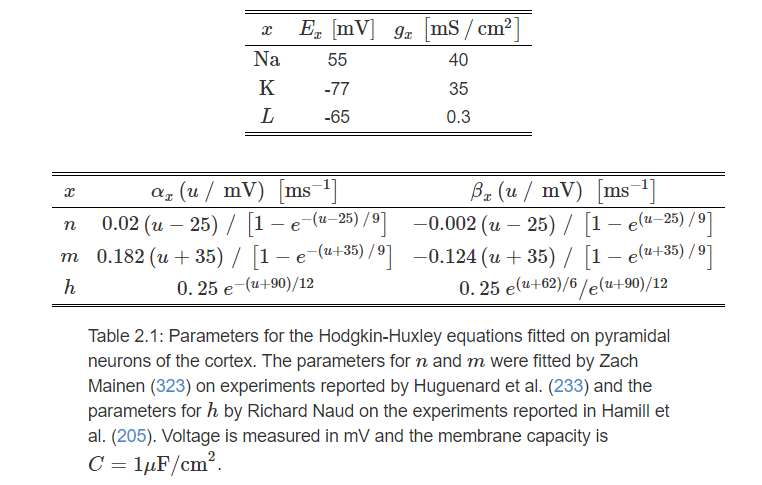

In our first simulation, we will inject $I_i$ (in $\textrm{mA}/{\textrm{mm}}^2$) current at t = 50 ms for 10 ms, and observe the spike.

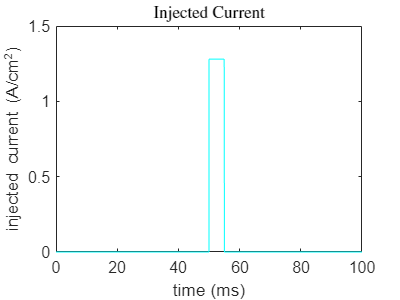

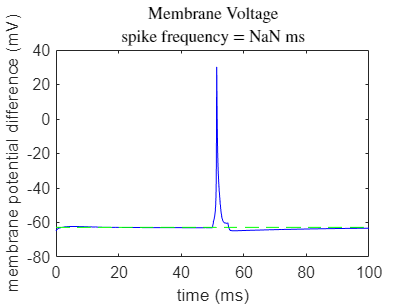

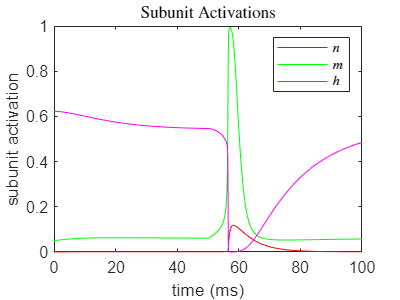

I_i = 1.28; % in uA/cm^2
accuracy = 0; % try I_i = 0.37 with Fast and you'll know why I added this
I_step = @(t) ((t > 50) - (t > 55)) * I_i; % the injection current has the unit uA/cm^2
hodgkin_huxley_hardcode_normal(100, I_step, NaN, "Vm0", -65, 'accuracy', accuracy);

We will inject $I_i$ (in $\textrm{mA}/{\textrm{mm}}^2$) current 20 ms after the start of the simulation, and the simulation will last for 300 ms (default). The simulation sets the initial voltage $V_m \left(t=0\right)$ as $-65\;\textrm{mV}$.

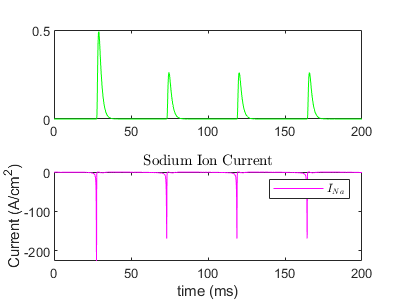

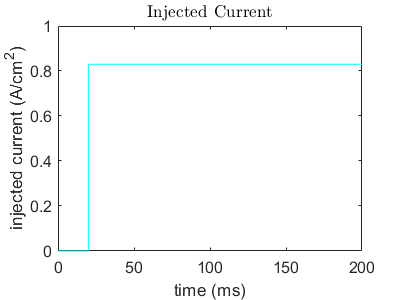

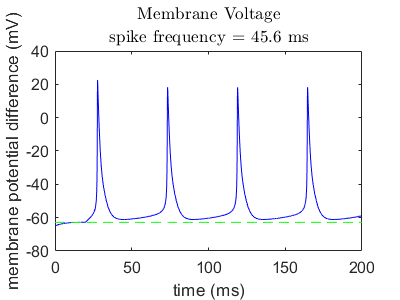

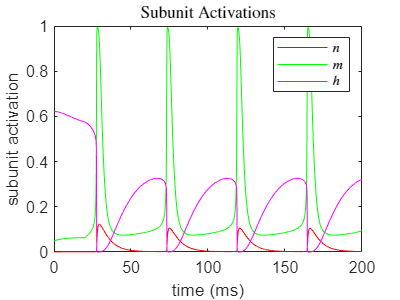

I_i = 0.83; % in uA/cm^2
accuracy = 1; % try I_i = 0.37 with Fast and you'll know why I added this
tf = 200; % in ms
I_step = @(t) (t > 20) * I_i; % the injection current has the unit uA/cm^2
hodgkin_huxley_hardcode_normal(tf, I_step, NaN, "Vm0", -65, 'accuracy', accuracy);

By playing with this, you can observe some characteristics of the action potential:

- The shape of the action potential is rather fixed.

- If a constant current passing a certain threshold is injected, there will be spike train. Larger the current, the more frequent the spikes. (Observe the spike frequency in the membrane voltage diagram.)

We can plot a graph of the frequency against the applied current. Run the following code segment to see the graph.

 
N = 50; % number of points to calculate
Imax = 3.9; % range of amplitude to try
II = linspace(0, Imax, N) * 1e-6;
freq = zeros(N, 1);
for i = 1:N
    I_step = @(t) (t > 20) * II(i);
    freq(i) = hodgkin_huxley_hardcode_normal(200, I_step, NaN, "Vm0", -65, 'accuracy', 1, 'getFreq', true);
end
figure(1);
plot(II, freq, "b-");
title("Spike Frequency vs Injected Current")
xlabel("injected current (mA/mm^2)")
ylabel("frequency (Hz)")

Note that this graph has a shape that matches the one on [2.2 Hodgkin-Huxley Model | Neuronal Dynamics online book (epfl.ch)](https://neuronaldynamics.epfl.ch/online/Ch2.S2.html), but the values are different. (I tried my best to debug but I'm tired :(.)

## Voltage Clamp

The following simulation applies a -45V voltage step at 20 ms, and returns to the resting membrane voltage (-65V) at 120 ms.

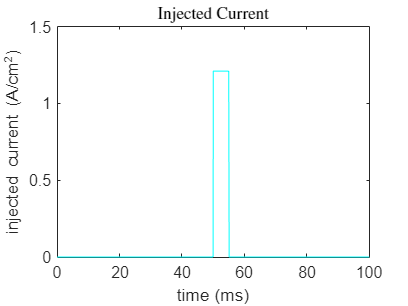

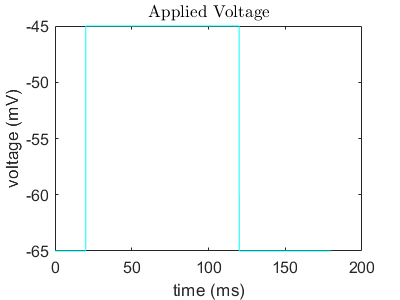

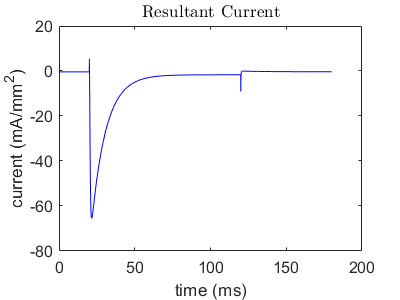

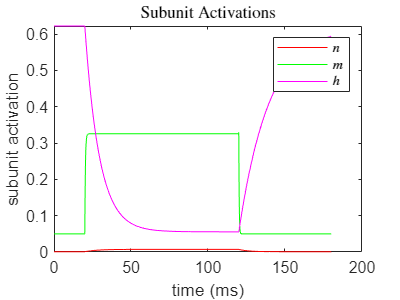

V = -8; % in mV
accuracy = 0; % try I_i = 0.37 with Fast and you'll know why I added this
V_step = @(x) -65 + (x > 20) * (65 - 45) + (x > 120) * (45 - 65);
hodgkin_huxley_hardcode_voltage_clamp(180, V_step, NaN, 'step', true, 'accuracy', accuracy)